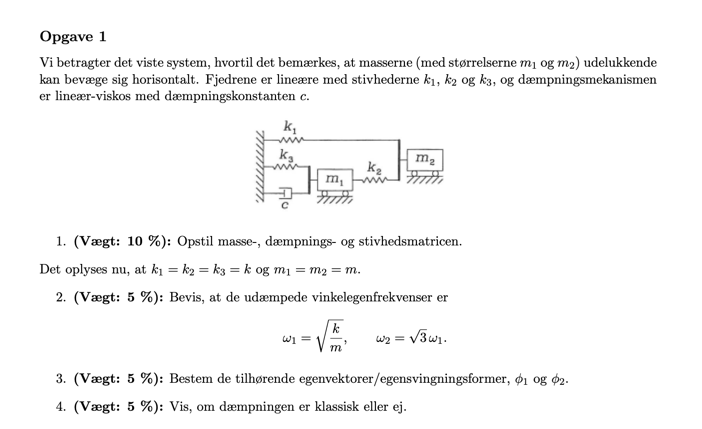

1.1 Vha Newtons 2. lov kan følgende udtryk opstilles for de to massers bevægelse


$$m_1 \ddot{d_1 } =-k_3 d_1 -c\;\dot{d_2 } +k_2 \left(d_2 -d_1 \right)\;\;\;\Rightarrow \;\;m_1 \ddot{d_1 } +k_3 d_1 +c\dot{d_1 } -k_2 \left(d_2 -d_1 \right)=0$$


og


$$m_2 \ddot{d_2 } =-k_2 \left(d_2 -d_1 \right)-k_1 d_2 \;\;\;\Rightarrow \;\;m_2 \ddot{d_2 } +k_2 \left(d_2 -d_1 \right)+k_1 d_2 =0$$


Disse kan samles til:


$$\left\lbrack \begin{array}{cc}
m_1  & 0\\
0 & m_2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\ddot{d_1 } \\
\ddot{d_2 } 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
c & 0\\
0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\dot{d_1 } \\
\dot{d_2 } 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
k_2 +k_3  & -k_2 \\
-k_2  & k_1 +k_2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
d_1 \\
d_2 
\end{array}\right\rbrack =0$$


Altså er masse-, dæmpnings- og stivhedsmatricerne hhv.


$$M=\left\lbrack \begin{array}{cc}
m_1  & 0\\
0 & m_2 
\end{array}\right\rbrack ,\;\;\;C=\left\lbrack \begin{array}{cc}
c & 0\\
0 & 0
\end{array}\right\rbrack ,\;\;\;K=\left\lbrack \begin{array}{cc}
k_2 +k_3  & -k_2 \\
-k_2  & k_1 +k_2 
\end{array}\right\rbrack$$


1.2 Med de givne størrelser fås følgende system


$$\left\lbrack \begin{array}{cc}
m & 0\\
0 & m
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\ddot{d_1 } \\
\ddot{d_2 } 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
c & 0\\
0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\dot{d_1 } \\
\dot{d_2 } 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
2k & -k\\
-k & 2k
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
d_1 \\
d_2 
\end{array}\right\rbrack =0$$


Vi har desuden, at vores karakteristiske ligning er


$$\det \left(K-\omega^2 M\right)=0$$


$\det \left(\left\lbrack \begin{array}{cc}
2k-\omega^2 m & -k\\
-k & 2k-\omega^2 m
\end{array}\right\rbrack \right)=0$ => ${\left(2k-\omega^2 m\right)}^2 -{\left(-k\right)}^2 =0$

Hvilket vi løser i MatLab som:

clear variables; clc; close all;

syms k omega m c positive
M = [m 0; 0 m];
C = [2*c  -c; -c   c  ];
K = [2*k  -k; -k   2*k];

% Karakteritisk ligning: det(K - omega^2 M) = 0
char_eq = det(K - omega^2*M);

disp("Karakteristisk ligning")

Karakteristisk ligning


pretty(char_eq)

   2          2    2  4
3 k  - 4 k m ω  + m  ω




% Solve for omega
omega_sol = solve(char_eq == 0, omega)

$$omega\_sol = \left(\begin{array}{c} \frac{\sqrt{k}}{\sqrt{m}}\\ \frac{\sqrt{3}\,\sqrt{k}}{\sqrt{m}} \end{array}\right)$$

Altså er det vist.

1.3

Her løser vi egenvektor-problemet:


$$\det \left(\left\lbrack \begin{array}{cc}
2k-\omega^2 m & -k\\
-k & 2k-\omega^2 m
\end{array}\right\rbrack \right)\left\lbrack \begin{array}{c}
\phi_1 \\
\phi_2 
\end{array}\right\rbrack =0$$


for begge vores egenværdier.

omega_1sq = k/m;
omega_2sq = 3 * k/m;

A1 = simplify(K - omega_1sq*M);

null(A1)

$$ans = \left(\begin{array}{c} 1\\ 1 \end{array}\right)$$


A2 = simplify(K - omega_2sq * M);

null(A2)

$$ans = \left(\begin{array}{c} -1\\ 1 \end{array}\right)$$

Altså får vi:


$$\phi_1 =\left\lbrack \begin{array}{c}
1\\
1
\end{array}\right\rbrack$$



$$\phi_2 =\left\lbrack \begin{array}{c}
-1\\
1
\end{array}\right\rbrack$$


1.4 Fra 1.3 har vi vores modalmatrice:


$$\Phi =\left\lbrack \begin{array}{c}
\phi_{1,1} \;\;\;\;|\;\;\;\;\phi_{2,1} \\
\phi_{1,2} \;\;\;\;|\;\;\;\;\phi_{2,2} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
1 & -1\\
1 & 1
\end{array}\right\rbrack$$


For at finde ud af om vores dæmpning er klassisk skal vi bestemme om den modale dæmpningsmatrice $\tilde{C}$ er diagonal. Denne er givet som:

$\tilde{C} =\Phi^T C\Phi \;$:

Phi = [1  -1; 1  1];
C   = [c   0; 0  0];

C_tilde = Phi' * C * Phi

$$C\_tilde = \left(\begin{array}{cc} c & -c\\ -c & c \end{array}\right)$$

Da $\tilde{C} =\left\lbrack \begin{array}{cc}
c & -c\\
-c & c
\end{array}\right\rbrack$ ikke er diagonal er vores dæmpning ikke klassisk.

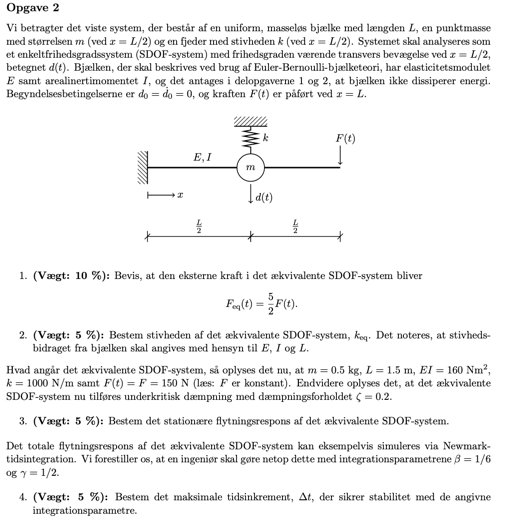

2.1

Vi benævner i denne opgavebesvarelse massens lokation som 1 og kraftens lokation som 2. Vha. DAlemberts princip kan følgende dermed opstilles


$$d\left(t\right)=\delta_{12} F\left(t\right)-\delta_{11} m\ddot{d} \left(t\right)-\delta_{11} k\;d\left(t\right)\;\;\;\Rightarrow \;\;\;\;m\ddot{d} \left(t\right)+\left(k+\frac{1}{\delta_{11} }\right)d\left(t\right)=\frac{\delta_{12} }{\delta_{11} }F\left(t\right)$$


Altså har vi at


$$m_{\textrm{eq}} =m,\;\;\;k_{\textrm{eq}} =k+\frac{1}{\delta_{11} },\;\;F_{\textrm{eq}} =\frac{\delta_{12} }{\delta_{11} }F\left(t\right)$$


For at finde $F_{eq}$ skal vi altså først bestemme fleksibilitetskoefficienterne $\delta_{11}, \delta_{12}$. Fra R. C. Hibbeler, *Statics and Mechanics of Materials*, 6th ed., Pearson, App. D har vi de elastiske kurver for knægtbjælker påvirket af en punkt-enhedslast i punkt 1 og punkt 2 som


$$\begin{array}{l}
v_1 \left(x\right)=-\frac{x^2 }{12\textrm{EI}}\left(3L-2x\right)\\
v_2 \left(x\right)=-\frac{x^2 }{6\textrm{EI}}\left(3L-x\right)
\end{array}$$


Evalueret i punkt 1 svarer disse til vores fleksibiliteskoefficienter


$$v_1 \left(P_1 \right)=\delta_{11}$$



$$v_2 \left(P_1 \right)=\delta_{12}$$


Altså får vi at

clear variables; clc; close all;

syms L EI positive

v_1 = @(x) x^2/(12 * EI) * (3 * L - 2 * x);
v_2 = @(x) x^2/(6 * EI) * (3 * L - x);

delta_11 = v_1(L/2);
delta_12 = v_2(L/2);

F_eqcoeff = delta_12/delta_11

$$F\_eqcoeff = \frac{5}{2}$$

Altså er det vist at koefficienten til $F_{\textrm{eq}}$ skal være 5/2. 

2.2

Vi har tidligere vist at $\;\;k_{\textrm{eq}} =k+\frac{1}{\delta_{11} }$. Altså er den ækvivalente stivhed

syms k

k_eq = k + 1/delta_11

$$k\_eq = k+\frac{24\,\mathrm{EI}}{L^{3}}$$

Altså er stivheden af det ækvivalente SDOF system $k_{\textrm{eq}} =k+\frac{24\textrm{EI}}{L^3 }$.

2.3 

Eftersom $F(t)$ er konstant er det stationære flytningsrespons blot


$$d_{\textrm{ss}} =\frac{F_{\textrm{eq}} }{k_{\textrm{eq}} }$$


Dette regnes i MatLab til

F = 150; % N

F_eq = F_eqcoeff * F; % N

EIval = 160; %Nm^2
Lval = 1.5; %m
kval = 1000; %N/m

k_eq_val = double(subs(k_eq,[L, EI, k],[Lval, EIval, kval]));

d_ss = double(F_eq/k_eq_val) %m

d_ss = 0.1754

Altså er den stationære flytningsrespons 0.175 m = 17.5 cm

2.4

Vi ved at Nemark-algoritmen er ubetinget stabil hvis $2\beta \geq \gamma \geq 1/2$. Med $\beta = 1/6$ og $\gamma = 1/2$ har vi $2\beta \not\geq \gamma$, hvorfor vores integrationsparametre ikke medfører ubetinget stabilitet.

Derudover ved vi at algoritmen er betinget stabil for


$$\Delta t\le \min \left(\frac{\Omega_j^{\textrm{cr}} }{\omega_j }\right),\;\;\;j=1,2,\ldots,n$$


hvor

$\Omega_j^{\textrm{cr}} =\frac{1}{\sqrt{\frac{1}{4}-\beta \;}}$ for $\gamma = 1/2$.

I dette tilfælde arbejder vi med et SDOF-system, hvorfor $n = 1$ og $\omega_j = \omega_1 = \omega_n$. 

Egenvinkelfrekvensen $\omega_n$ kan findes som

$\omega_n = \sqrt{\frac{k_{eq}}{m}}$, hvilket regnes i MatLab til

m = 0.5; %kg
omega_n = sqrt(k_eq_val/m); %rad/s

Altså kan vores maksimale tilladelige tidsinkrement findes som

beta = 1/6;
Omega_jcr = 1/(sqrt(1/4 - beta));

delta_t_max = Omega_jcr/omega_n

delta_t_max = 0.0530

Altså er vores maksimale tilladelige tidsinkrement der sikrer stabilitet med de angivne integrationsparametre $\Delta t_{max} = 0.053$ s. 

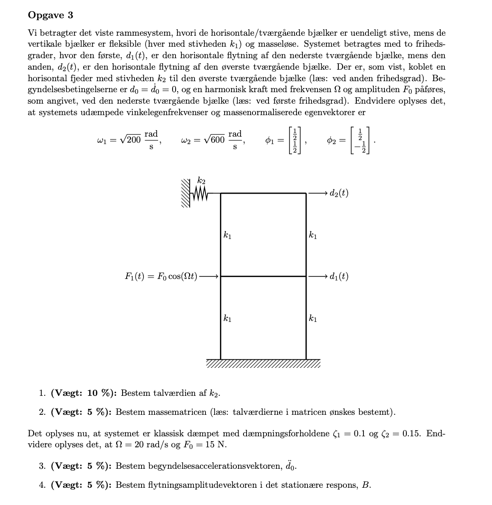

3.1

clc; clear variables; close all;

Vi har hhv. vores spektral-, modal- og modalmassematrice som


$$\Lambda =\left\lbrack \begin{array}{cc}
200 & 0\\
0 & 600
\end{array}\right\rbrack ,\;\;\;\;\;\Phi =\left\lbrack \begin{array}{cc}
\frac{1}{2} & \frac{1}{2}\\
\frac{1}{2} & -\frac{1}{2}
\end{array}\right\rbrack ,\;\;\;\;\;\tilde{M} =I$$


Vi har


$$\tilde{K} =\Lambda =\left\lbrack \begin{array}{cc}
200 & 0\\
0 & 600
\end{array}\right\rbrack$$



$$K={\Phi^T }^{-1} \tilde{K} \Phi^{-1} ={\Phi^T }^{-1} \Lambda \Phi^{-1}$$


Altså kan vores dæmpningsmatrice $K$ findes i Matlab som

Phi    = [1/2    1/2;    1/2    -1/2];
Lambda = [200      0;      0     600];

K = (Phi')^-1 * Lambda * Phi^-1

K =    800  -400
  -400   800


Altså er vores dæmpningsmatrice


$$K=\left\lbrack \begin{array}{cc}
800 & -400\\
-400 & 800
\end{array}\right\rbrack$$


Vi har fra Newtons 2. lov at


$$K=\left\lbrack \begin{array}{cc}
4k_1  & -2k_1 \\
-2k_1  & 2k_1 +k_2 
\end{array}\right\rbrack$$


Altså ser vi at $k_1 = 200, k_2 = 400$.

3.2

Vi har at


$$\tilde{M} =\Phi^T M\Phi \;\;\;\Rightarrow \;\;\;M={\Phi^T }^{-1} I\Phi^{-1} ={\Phi^T }^{-1} \Phi^{-1}$$


Altså

M = (Phi')^-1 * Phi^-1

M =      2     0
     0     2


Altså er $m_1 = m_2 = 2$.

3.3

Vi har at


$$M\;\ddot{d_0 } +C\;\dot{d_0 } +k\;d_0 =F_o$$


Idet $\dot{d_0 } =d_0 =0$ får vi


$$M\;\ddot{d_0 } =F_0 \;\;\Rightarrow \ddot{d_0 } =M^{-1} F_0$$


F_0 = [15; 0];

ddd_0 = M^-1 * F_0

ddd_0 =     7.5000
         0


Altså er vores begyndeslesaccelerationsvektor


$$\ddot{d_0 } =\left\lbrack \begin{array}{c}
7\ldotp 50\\
0
\end{array}\right\rbrack$$


3.4

Vi har for en harmonisk respons $F\left(t\right)=F_0 \cos \left(\omega \;t\right)$, at flytningsamplituden i den stationære respons $B_j$ er den j'te komponent af $|{H\left(\omega \;\right)F}_0 |$, hvor $H(\omega)$ er den dynamiske fleksibilitetsmatrice defineret som


$$H\left(\omega \right)={\left(-M\omega^2 +C\;i\omega +K\right)}^{-1}$$


For at kunne finde $H(\omega)$ skal vi først finde $C$. For at gøre dette finder vi først $\tilde{C}$ som


$$\tilde{C} =\left\lbrack \begin{array}{cc}
2\zeta_1 \omega_1  & 0\\
0 & 2\zeta_2 \omega_2 
\end{array}\right\rbrack$$


zeta_1 = 0.1;
zeta_2 = 0.15;
omega_1 = sqrt(200);
omega_2 = sqrt(600);

C_tilde = [2 * zeta_1 * omega_1    0; 0       2 * zeta_2 * omega_2];

Denne kan nu omregnes til dæmpningsmatricen $C$ som


$$C={\Phi^T }^{-1} \tilde{C} \Phi^{-1}$$


C = (Phi')^-1 * C_tilde * Phi^-1;

Dermed kan vi nu finde vores dynamiske fleksibilitetsmatrice ved vores lastfrekvens $\Omega = 20$ som:


$$H\left(20\right)={\left(-M{\cdot 20}^2 +C\;i\cdot 20+K\right)}^{-1}$$


Omega = 20;

H = (-M * Omega^2 + C * 1i * 20 + K)^-1;

Og dernæst har vi at


$$B_j =|H\left(\omega \right)F_0 |_j$$


B = abs(H * F_0)

B =     0.0148
    0.0298


Altså er flytningsamplituden i den stationære respons


$$B=\left\lbrack \begin{array}{c}
0\ldotp 0148\\
0\ldotp 0298
\end{array}\right\rbrack$$


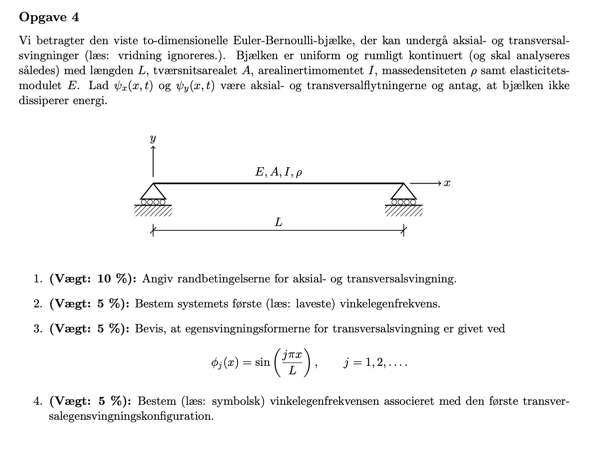

clc; clear variables; close all;

4.1

Understøttelserne hindrer transversal bevægelse i y-aksen


$$\psi_y \left(0,t\right)=0\;\;\;\Rightarrow \;\phi_j^y \left(0\right)=0$$



$$\psi_y \left(L,t\right)=0\;\;\;\Rightarrow \;\phi_j^y \left(L\right)=0$$


Undersøttelserne kan ej heller modstå et moment


$$\frac{d^2 \psi_y \left(0,t\right)}{x^2 }=0\;\;\;\Rightarrow \;\;\;{{\phi_j^y }^{\prime } }^{\prime } \left(0\right)=0$$



$$\frac{d^2 \psi_y \left(L,t\right)}{x^2 }=0\;\;\;\Rightarrow {{\;\;\;\phi_j^y }^{\prime } }^{\prime } \left(L\right)=0$$


Derudover er tøjningen 0 for begge understøtninger idet de ikke modstår en aksial fritlegemebevægelse


$$\frac{d\psi_x \left(0,t\right)}{x}=0\;\;\;\Rightarrow \;\;\;{\phi_j^x }^{\prime } \left(0\right)=0$$



$$\frac{d\psi_x \left(L,t\right)}{x}=0\;\;\;\Rightarrow \;\;\;{\phi_j^x }^{\prime } \left(L\right)=0$$


4.2

Idet firtlegemebevægelse ikke er hindret i den aksiale retning vil den første vinkelegenfrekvens være knyttet til selvsamme fritlegemebevægelse således at


$$\omega_1 =0$$


for aksial fritlegemebevægelse.

4.3 

Vi verficerer at det givne udtryk overholder randbetingelserne:

syms L
syms j integer
phi_j = @(x) sin (j * pi * x / L);

phi_j(0)

$$ans = 0$$

simplify(phi_j(L))

$$ans = 0$$

Altså er det vist at den givne formel for egensvingen overholder randbetingelserne.

4.4

Vi har


$$\epsilon_j =\sqrt{\frac{\omega_j^y }{\eta \;}}\;\Rightarrow \omega_j^y =\epsilon^2 \eta \;$$


og


$$\eta =\sqrt{\frac{\textrm{EI}}{\rho \;A}}$$


Vi har fra opgaven at


$$\phi_j^y \left(x\right)=\sin \left(\frac{j\pi \;x}{L}\right)$$


hvor vi ved at


$$\epsilon_j =\frac{\;j\pi \;}{L}\;\;\;\Rightarrow \;\phi_j^y \left(x\right)=\sin \left(\epsilon_j x\right)$$


Vi får dermed at


$$\omega_j^y =\frac{j^2 \pi^2 }{L^2 }\eta =\frac{j^2 \pi^2 }{L^2 }\sqrt{\frac{\textrm{EI}}{\rho \;A}}\;\;\;\Rightarrow \;\;\;\;\;\omega_1^y =\frac{\pi^2 }{L^2 }\sqrt{\frac{\textrm{EI}}{\rho \;A}}$$
